# Regelung von Robotern

# Teil 1: Regelung der Lage bzw. von Trajektorien

%bdclose all    % close all Simulink models
close all      % close all figures
clear          % clear all workspace variables
format compact % compact printout 

## Laden des Modell des Roboters ABB IRB 120

[robot,robotdata] = loadrobot('kukaIiwa14',DataFormat='row',Gravity=[0,0,-9.81]);
%show(robot);

Gelenkkonfiguration in Nullstellung

qhome = homeConfiguration(robot)

qhome =      0     0     0     0     0     0     0


Transformationsmatrix für Nullstellung

EE = "iiwa_link_ee";
T = robot.getTransform(qhome, EE)

T =     0.0000   -0.0000   -1.0000    0.0000
    0.0000    1.0000   -0.0000    0.0000
    1.0000    0.0000    0.0000    1.3060
         0         0         0    1.0000


## Spezifikation einer Bewegungsaufgabe im Arbeitsraum

### Spezifikationen von Positionen (Bahnpunkte) im Arbeitsraum (Orientierung bleibt konstant)

wayPoints = [0.0,-0.1,-0.3,-0.5,-0.6,-0.6,-0.6;    
            -0.8,-0.6,-0.5,-0.4,-0.3,-0.2,-0.1;
             0.6,0.6,0.6,0.6,0.6,0.5,0.5;
            -pi/2,-pi/2,-pi/1.6,-pi/1.3,-pi,-pi,-pi;
             0.0,0.0,0.0,0.0,0.0,0.0,0.0;
             0.0,0.0,0.0,0.0,0.0,0.0,0.0;
             ];

P0 = wayPoints(:,1);
P1 = wayPoints(:,2);
P2 = wayPoints(:,3);
P3 = wayPoints(:,4);
P4 = wayPoints(:,5);
P5 = wayPoints(:,6);
P6 = wayPoints(:,7);

sample = 300;

numWaypoints = size(wayPoints,2);

#### Inverse Kinematik

ik = inverseKinematics('RigidBodyTree',robot);
weights = [1,1,1,1,1,1];
T1 = trvec2tform(P0(1:3)')* eul2tform(P0(4:6)');
C1 = ik(EE,T1,weights,qhome);
T2 = trvec2tform(P1(1:3)')* eul2tform(P1(4:6)');
C2 = ik(EE,T2,weights,C1);
T3 = trvec2tform(P2(1:3)')* eul2tform(P2(4:6)');
C3 = ik(EE,T3,weights,C2);
T4 = trvec2tform(P3(1:3)')* eul2tform(P3(4:6)');
C4 = ik(EE,T4,weights,C3);
T5 = trvec2tform(P4(1:3)')* eul2tform(P4(4:6)');
C5 = ik(EE,T5,weights,C4);
T6 = trvec2tform(P5(1:3)')* eul2tform(P5(4:6)');
C6 = ik(EE,T6,weights,C5);
T7 = trvec2tform(P6(1:3)')* eul2tform(P6(4:6)');
C7 = ik(EE,T7,weights,C6);


#### Trajektorie im Gelenkraum mit trapezförmigen Geschwindigkeitsprofil

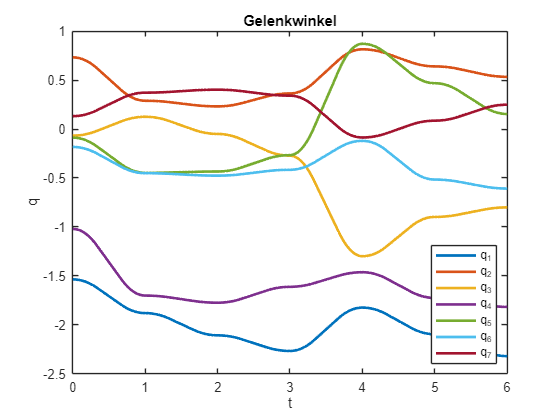

[q,qd,qdd,qtrajpoints] = trapveltraj([C1', C2', C3', C4', C5', C6', C7'],sample,EndTime=1);
figure;
plot(qtrajpoints,q,'LineWidth',2)
xlabel('t');
ylabel('q');
legend('q_1','q_2','q_3','q_4','q_5','q_6','q_7',Location='southeast')
title('Gelenkwinkel');

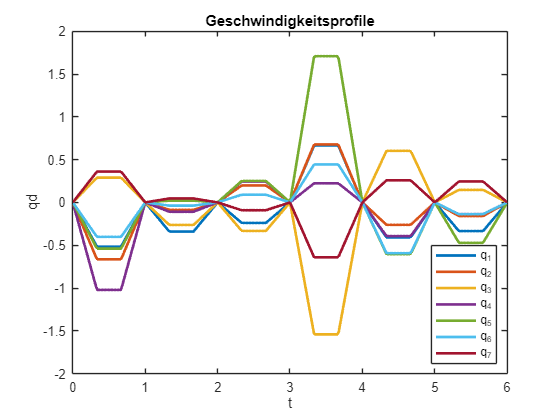

figure;
plot(qtrajpoints,qd,'LineWidth',2)
xlabel('t');
ylabel('qd');
legend('q_1','q_2','q_3','q_4','q_5','q_6', 'q_7',Location='southeast')
title('Geschwindigkeitsprofile');

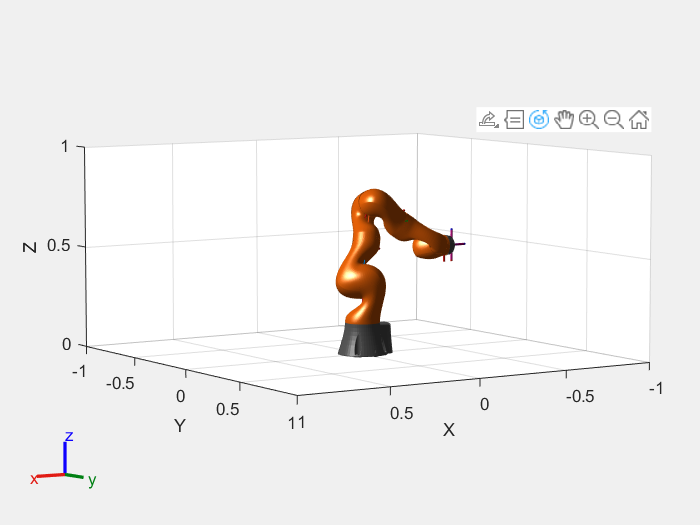


figure;
ax = show(robot, q(:,end).'); % Erstes Frame anzeigen
hold on;
xlim([-1 1]); ylim([-1 1]); zlim([0 1]); % Achsenbegrenzungen setzen

% Animationsschleife
for i = 1:size(q, 2)
    show(robot, q(:,i).', 'PreservePlot', false, 'Parent', ax);
    pause(0.01); % Zeitverzögerung für flüssige Animation
end